# Read All Worksheets from Spreadsheet File 

This example shows how to import worksheets in an Excel® file. Gather information about the spreadsheet, import the worksheets into the workspace, and then analyze the imported data.   

## Gather Information about Worksheets

For this example, we will be using the spreadsheet file '`airlinessmall_subset.xlsx`'  which contains mixed data in multiple worksheets, organized by the year. The file contains `13` worksheets of column-oriented data and each worksheet contains `29` columns. The preview here shows the first `10` rows and columns from the worksheet named '`1996`'. 

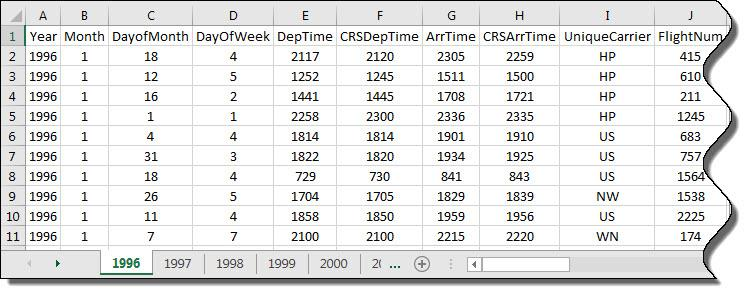

Get the names of all the worksheets and display the total number of spreadsheets present in the file. 

[~,SheetNames]  = xlsfinfo('airlinesmall_subset.xlsx')
nSheets = length(SheetNames)

## Import the Worksheets 

Import worksheets, one at a time, and organize them in a structure array `S`. For instance, import the first worksheet into `S(1).Data`, the second worksheet into `S(2).Data,` and the last worksheet into `S(nSheets).Data`. 

 for iSheet = 1:nSheets
  Name = SheetNames{iSheet}; 
  Data = readtable('airlinesmall_subset.xlsx','Sheet',Name) ; 
  S(iSheet).Name = Name;
  S(iSheet).Data = Data;
 end

## Examine Imported Data

Examine the structure array. The size of `S `should correspond to the number of worksheets in the file which is `13`. 

 S

Retrieve the first `10` rows and columns from the worksheet '`1996`' and verify if they match the data in the spreadsheet.

 S(1).Name
 S(1).Data(1:10,1:10)

## Compute and Display Maximum Arrival Delay for Each Year

Each worksheets in the `airlinesmall_subset.xls` contains data for one year. Within the worksheet the variable `ArrDelay `captures the arrival delay in minutes. Using the imported data from the structure `S `and compute the maximum arrival day for each year. 

maxDelay = zeros(nSheets,1);
for iSheet = 1:nSheets
    ArrDelay = S(iSheet).Data.ArrDelay; 
    maxDelay(iSheet) = max(ArrDelay);
end

Display the maximum arrival delay for each year.

year = 1996:2008 ;     
maxDelayInHours = maxDelay/60; % Convert to hours
plot(year,maxDelayInHours,'-o','LineWidth',2);
xlabel('Year')
ylabel('Maximum Delay (hours)')
title('Flight Delay Trend by Year')

*Copyright 2012 The MathWorks, Inc.*